# Task 2 - GMM model

clc
clear all
[training_set, testing_set, vowel_code, talker_group_code, talker_number, vowel_classes] = prepare_data();

## (a) Finding GMM models

GMM2 = GMM_model(training_set, vowel_code, 2);
GMM3 = GMM_model(training_set, vowel_code, 3);

## (b) Classify

targets = get_targets(testing_set, vowel_classes);

targets =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


predicted_classes_gmm2 = GMM_classifier(testing_set, GMM2);
predicted_classes_gmm3 = GMM_classifier(testing_set, GMM3);

## (c) Find confusion matrices and error rates

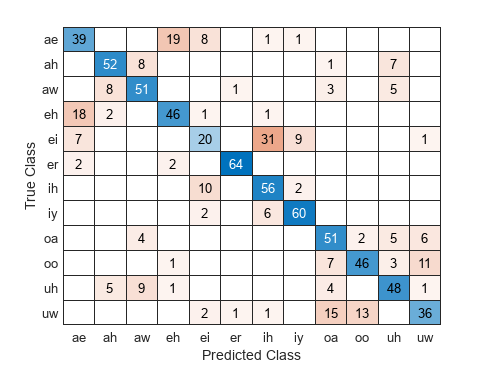

cm = confusionmat(targets, predicted_classes_gmm2);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_gmm2.png")

error_rate = 1 - (trace(cm) / sum(cm, 'all'))

error_rate = 0.3027

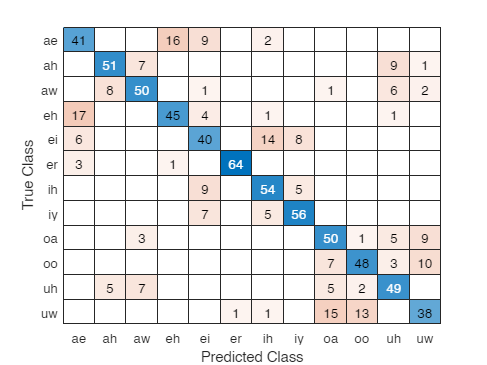

cm = confusionmat(targets, predicted_classes_gmm3);
confusionchart(cm, string(vowel_classes))
saveas(gca, "figs/confmat_gmm3.png")

error_rate = 1 - (trace(cm) / sum(cm, 'all'))

error_rate = 0.2819